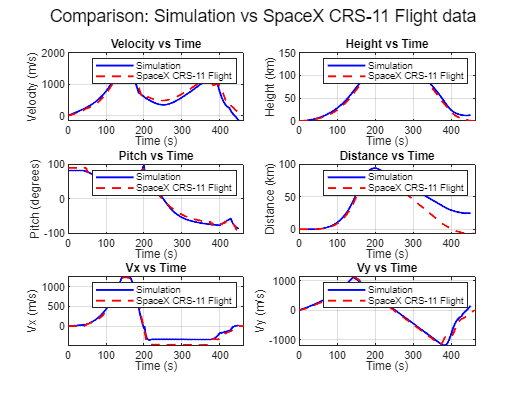

% Clear environment
clear;

% Load main data
filename = 'rocket_trajectory.csv';
data = readtable(filename);

% Extract columns
time = data.Time;
velocity = data.Velocity;
height = data.Height;
vx = data.Vx;
vy = data.Vy;
angle = data.Angle; 
% 90-angle as co-ordinate systems are different so mine starts at 0
% pointing straight up but theres is 90 degrees pointing up so by doing 
% 90-angle = conversion
theta = data.Theta;
distance = data.Distance;

% Load comparison data
filenameData = 'analysed.csv';
Adata = readtable(filenameData);

% Extract columns
Atime = Adata.time;
Avelocity = Adata.velocity;
Aheight = Adata.altitude;
Avx = Adata.velocity_x;
Avy = Adata.velocity_y;
Aangle = Adata.angle;
Apsi2 = Adata.q;
Adistance = Adata.downrange_distance;

% Create figure for comparison plots
figure;

% Velocity vs Time
subplot(3,2,1);
plot(time, velocity, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Avelocity, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Velocity (m/s)');
title('Velocity vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% Height vs Time
subplot(3,2,2);
plot(time, height, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Aheight, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Height (km)');
title('Height vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% Pitch (Angle) vs Time
subplot(3,2,3);
plot(time, angle, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Aangle, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Pitch (degrees)');
title('Pitch vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% Distance vs Time
subplot(3,2,4);
plot(time, distance, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Adistance, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Distance (km)');
title('Distance vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% VX vs Time
subplot(3,2,5);
plot(time, vx, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Avx, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Vx (m/s)');
title('Vx vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% VY vs Time
subplot(3,2,6);
plot(time, vy, '-b', 'LineWidth', 1.5); hold on;
plot(Atime, Avy, '--r', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Vy (m/s)');
title('Vy vs Time'); grid on;
legend('Simulation', 'SpaceX CRS-11 Flight');

% Adjust layout
sgtitle('Comparison: Simulation vs SpaceX CRS-11 Flight data');

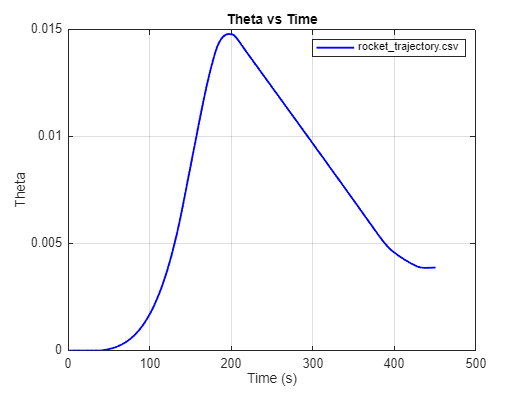


% theta vs Time
figure;
plot(time, theta, '-b', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Theta');
title('Theta vs Time'); grid on;
legend('rocket\_trajectory.csv');

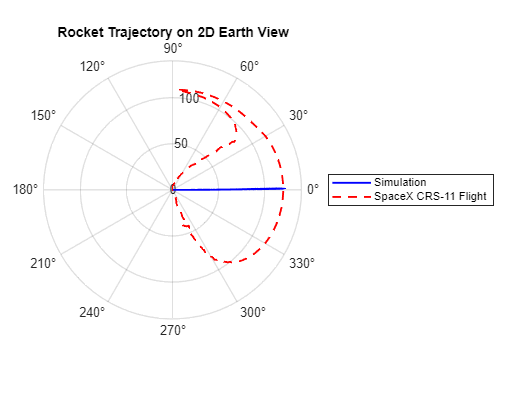


% Optional: 2D trajectory in polar coordinates
figure;
polarplot(deg2rad(angle), height, '-b', 'LineWidth', 1.5); hold on;
polarplot(deg2rad(Aangle), Aheight, '--r', 'LineWidth', 1.5);
title('Rocket Trajectory on 2D Earth View');
legend('Simulation', 'SpaceX CRS-11 Flight');

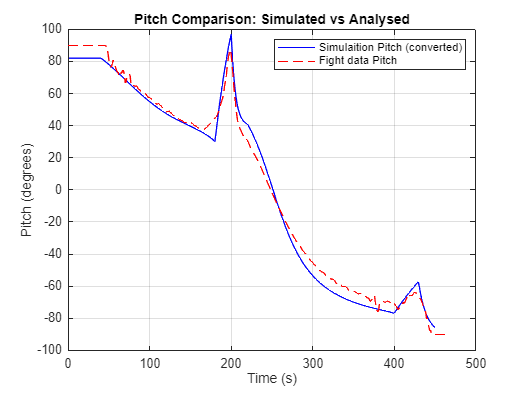


% Convert your pitch to match theirs
convertedPitch =  angle;

% Now you can compare:
figure;
plot(time, convertedPitch, 'b', 'DisplayName', 'Simulaition Pitch (converted)');
hold on;
plot(Atime, Aangle, 'r--', 'DisplayName', 'Fight data Pitch');
xlabel('Time (s)');
ylabel('Pitch (degrees)');
legend;
title('Pitch Comparison: Simulated vs Analysed');
grid on;